# Equilibrium Time Heat Distribution

clear, clc;

L = 100;
H = 100;
u = zeros(H, L);

[x,y] = meshgrid(1:1:H,1:1:L);

% bc = ones(H,1)'; % Just one side of the 2D plate is under some temperature distribution, other three sides are at 0 degrees
bc = sin(2*pi*(1:H)/H);

colormap("jet")

## Use Fourier Series

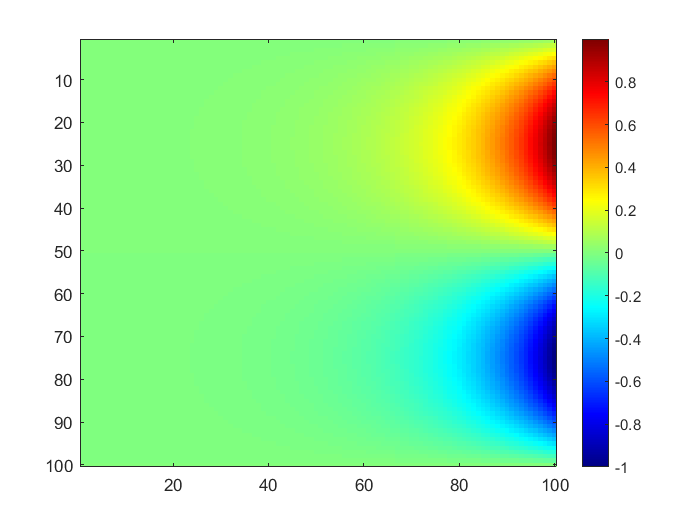

for i=1:100
    An = (2/(H*sinh(i*pi*L/H))) * sum(bc.*sin(i*pi*(1:H)/H));
    u = u + An * sin(i*pi*y/H) .* sinh(i*pi*x/H);
end

imagesc(u);
colorbar;